format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)


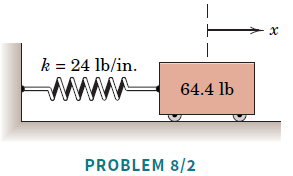

k = 4500 %*u.N / u.mm;

k =         4500


m = 20 %*u.kg;

m =     20



omega_n = sqrt(k/m)

omega_n =     15


f_n = omega_n / (pi * 2)

f_n =        2.3873


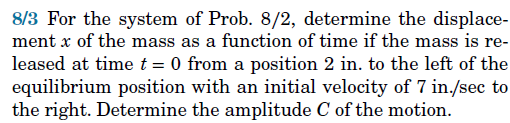

x_0 = -30; %*u.mm
V_0 = 120; %*u.mm /u.s;

psi = atan(x_0 * omega_n / V_0)

psi =       -1.3102



A = x_0 

A =    -30


B = V_0 / omega_n

B =      8



C = sqrt(A^2 + B^2 )

C =        31.048


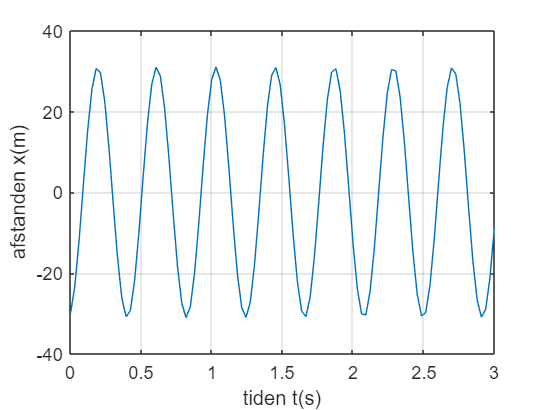



t = linspace(0,3,100);

x = @(t) C * sin(omega_n * t + psi);


plot(t, x(t))
grid()

xlabel('tiden t(s)')
ylabel('afstanden x(m)')

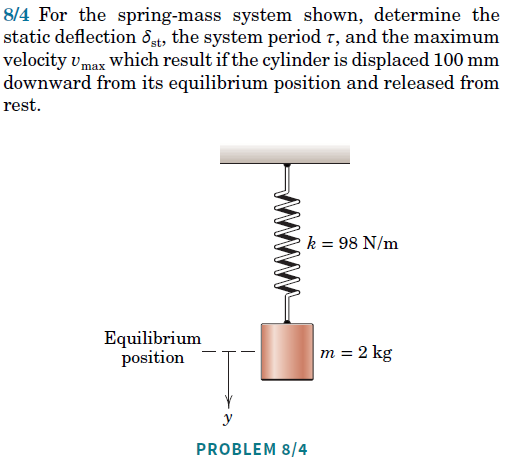

clear

x_0 = 0.1; %*u.m
V_0 = 0; %*u.m /u.s;

k = 98; %*u.N / u.mm;
m = 2; %*u.kg;
g = 9.82;


Vi finder egensvingninen $\omega_n$   og egen frekvensen $f_n$

omega_n = sqrt(k/m)

omega_n =      7


f_n = omega_n / (pi * 2)

f_n =        1.1141


tau = (pi * 2) / omega_n  %s

tau =        0.8976



delta = m*g/k

delta =       0.20041



psi = atan(x_0 * omega_n / V_0)

psi =        1.5708



A = x_0 

A =           0.1


B = V_0 / omega_n

B =      0



C = sqrt(A^2 + B^2 )

C =           0.1




T = linspace(0,3,100);

syms x(t)
x(t) = C * sin(omega_n * t + psi)

$$x(t) = \frac{\sin\left(7\,t+\frac{\pi }{2}\right)}{10}$$

v(t) = diff(x(t),t)

$$v(t) = \frac{7\,\cos\left(7\,t+\frac{\pi }{2}\right)}{10}$$


xt_0 = solve(x(t) == 0, t)

$$xt\_0 = \frac{\pi }{14}$$

% v = @(t) diff(C * sin(omega_n * t + psi), t);
v_max = v(xt_0)

$$v\_max = -\frac{7}{10}$$

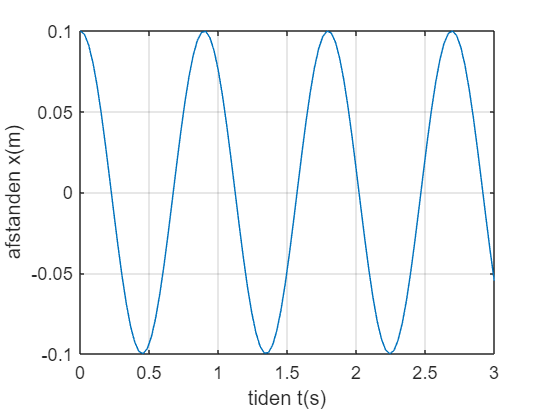


plot(T, x(T))
grid()

xlabel('tiden t(s)')
ylabel('afstanden x(m)')

8/6, 8/12, 8/13, 8/16, 8/17, 8/18

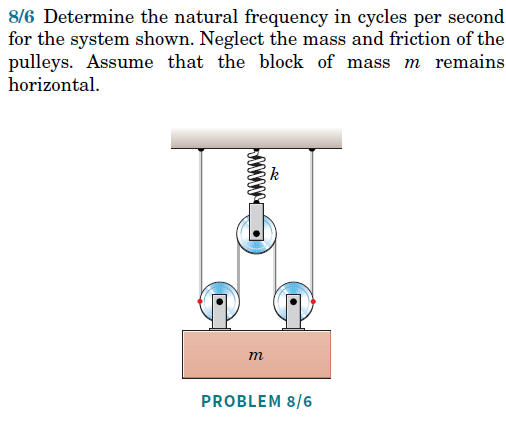

Her skal det ses som at vinkelhastigheden er dobbelt da vi kan se det røde punkt som stående stille og det modsatte punkt køre med dobblet vikelhastighed. 

clear
syms m k 
omega_n = sqrt(k/m) 

$$omega\_n = \sqrt{\frac{k}{m}}$$

f_n = 2 * omega_n / (pi * 2)

$$f\_n = \frac{\sqrt{\frac{k}{m}}}{\pi }$$

% tau = (pi * 2) / omega_n  %s


Med m/4

clear
syms m k 
m = m/4;
omega_n = sqrt(k/m) 

$$omega\_n = 2\,\sqrt{\frac{k}{m}}$$

f_n = omega_n / (pi * 2)

$$f\_n = \frac{\sqrt{\frac{k}{m}}}{\pi }$$

% tau = (pi * 2) / omega_n  %s
